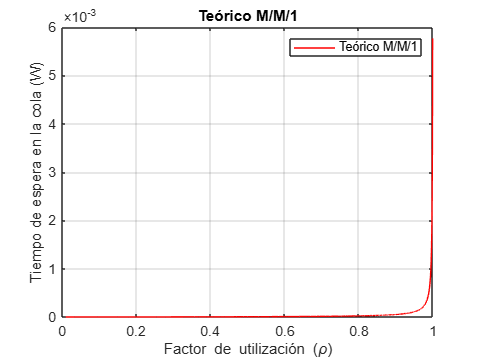

clear all;
clear clc;
rng(20223806);

% Instancie los parámetros de la simulación
N = 10^5; % Número de muestras
lambda = [24400 30000 39200 49400 77600 103000 145200 160200 168400 172600]; % Nuevo arreglo de valores de llegada
velocidad_transmision = 867 * 10^6; % Tasa de transmisión en bits por segundo
pkt_size = 625 * 8; % Tamaño de paquete en bits (625 bytes * 8 bits por byte)
mu = velocidad_transmision / pkt_size; % Tasa de servicio en pps

% Llamamos a la función principal para obtener resultados experimentales
resultados = comparacion_mm1_md1(lambda, velocidad_transmision, pkt_size, N);
resultados_md1 = resultados.MD1;
resultados_mm1 = resultados.MM1;

% Valores teóricos
rho_vals = 0.01:0.0001:0.999;
W_theoretical_MM1 = rho_vals ./ (mu * (1 - rho_vals));
W_theoretical_MD1 = rho_vals ./ (2 * mu * (1 - rho_vals));

% Graficar M/M/1 teórico
figure;
plot(rho_vals, W_theoretical_MM1, 'r-', 'DisplayName', 'Teórico M/M/1');
xlabel('Factor de utilización (\rho)');
ylabel('Tiempo de espera en la cola (W)');
title('Teórico M/M/1');
legend('show');
grid on;

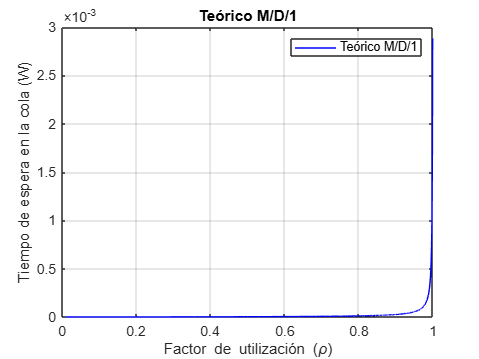


% Graficar M/D/1 teórico
figure;
plot(rho_vals, W_theoretical_MD1, 'b-', 'DisplayName', 'Teórico M/D/1');
xlabel('Factor de utilización (\rho)');
ylabel('Tiempo de espera en la cola (W)');
title('Teórico M/D/1');
legend('show');
grid on;

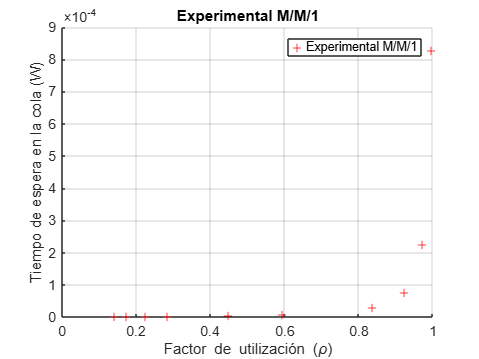


% Graficar M/M/1 experimental
figure;
rho_exp_mm1 = resultados_mm1(:, 1) / mu;
scatter(rho_exp_mm1, resultados_mm1(:, 2), 'r+', 'DisplayName', 'Experimental M/M/1');
xlabel('Factor de utilización (\rho)');
ylabel('Tiempo de espera en la cola (W)');
title('Experimental M/M/1');
legend('show');
grid on;

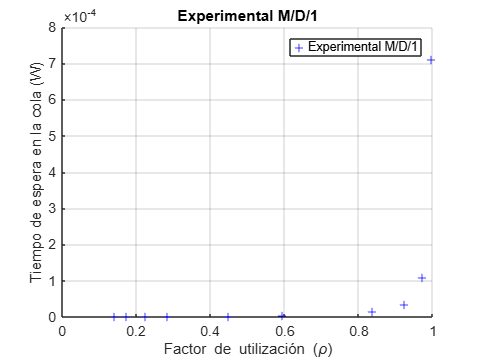


% Graficar M/D/1 experimental
figure;
rho_exp_md1 = resultados_md1(:, 1) / mu;
scatter(rho_exp_md1, resultados_md1(:, 2), 'b+', 'DisplayName', 'Experimental M/D/1');
xlabel('Factor de utilización (\rho)');
ylabel('Tiempo de espera en la cola (W)');
title('Experimental M/D/1');
legend('show');
grid on;

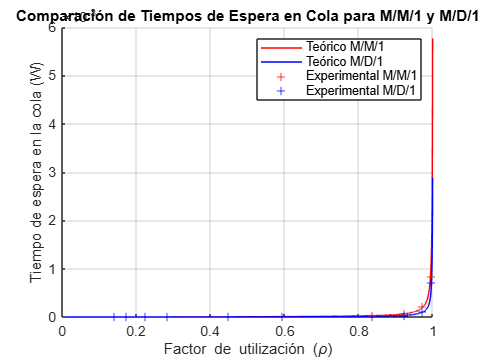


% Graficar todos juntos
figure;
hold on;
plot(rho_vals, W_theoretical_MM1, 'r-', 'DisplayName', 'Teórico M/M/1');
plot(rho_vals, W_theoretical_MD1, 'b-', 'DisplayName', 'Teórico M/D/1');
scatter(rho_exp_mm1, resultados_mm1(:, 2), 'r+', 'DisplayName', 'Experimental M/M/1');
scatter(rho_exp_md1, resultados_md1(:, 2), 'b+', 'DisplayName', 'Experimental M/D/1');
xlabel('Factor de utilización (\rho)');
ylabel('Tiempo de espera en la cola (W)');
title('Comparación de Tiempos de Espera en Cola para M/M/1 y M/D/1');
legend('show');
grid on;
hold off;


% Función principal para comparar M/M/1 y M/D/1
function resultados = comparacion_mm1_md1(arrival_rates, transmision_rate, packet_size, n_samples)
    % Inicializamos matrices para almacenar los resultados
    resultados_md1 = zeros(length(arrival_rates), 3); % [lambda, W, T] para M/D/1
    resultados_mm1 = zeros(length(arrival_rates), 3); % [lambda, W, T] para M/M/1

    % Iteramos sobre cada valor de lambda en el arreglo
    for i = 1:length(arrival_rates)
        arrival_rate = arrival_rates(i);

        % Generamos las llegadas en base al número de muestras
        arrival_times = genera_poisson(arrival_rate, n_samples);

        % Para el caso de M/D/1
        pkt_sizes_md1 = packet_size * ones(1, n_samples);
        pkt_duration_md1 = pkt_sizes_md1 / transmision_rate;
        depature_times_md1 = get_departure_times(arrival_times, pkt_duration_md1);
        sistem_time_md1 = depature_times_md1 - arrival_times;
        tiempo_promedio_sistema_md1 = mean(sistem_time_md1);
        queue_time_md1 = depature_times_md1 - pkt_duration_md1 - arrival_times;
        mean_queue_time_md1 = mean(queue_time_md1);

        % Guardamos resultados para M/D/1
        resultados_md1(i, :) = [arrival_rate, mean_queue_time_md1, tiempo_promedio_sistema_md1];

        % Para el caso de M/M/1
        mean_packet_size = 1 / packet_size;
        pkt_sizes_mm1 = genera_exponencial(mean_packet_size, n_samples);
        pkt_duration_mm1 = pkt_sizes_mm1 / transmision_rate;
        depature_times_mm1 = get_departure_times(arrival_times, pkt_duration_mm1);
        sistem_time_mm1 = depature_times_mm1 - arrival_times;
        tiempo_promedio_sistema_mm1 = mean(sistem_time_mm1);
        queue_time_mm1 = depature_times_mm1 - pkt_duration_mm1 - arrival_times;
        mean_queue_time_mm1 = mean(queue_time_mm1);

        % Guardamos resultados para M/M/1
        resultados_mm1(i, :) = [arrival_rate, mean_queue_time_mm1, tiempo_promedio_sistema_mm1];
    end

    % Devolvemos los resultados en una estructura
    resultados.MD1 = resultados_md1;
    resultados.MM1 = resultados_mm1;
end

% Funciones auxiliares

% Función para calcular tiempos de partida
function departure_times = get_departure_times(arrival_times, tx_delay)
    N = length(arrival_times);
    departure_times = zeros(1, N);
    departure_times(1) = arrival_times(1) + tx_delay(1);

    for i = 2:N
        if departure_times(i-1) <= arrival_times(i)
            departure_times(i) = arrival_times(i) + tx_delay(i);
        else
            departure_times(i) = departure_times(i-1) + tx_delay(i);
        end
    end
end

% Función para generar tiempos de llegada usando distribución Poisson
function out = genera_poisson(lambda, N)
    inter_arrivals = genera_exponencial(lambda, N);
    cumulative = conv(inter_arrivals, ones(1, N));
    out = cumulative(1:N);
end

% Función para generar tiempos de servicio exponenciales
function out = genera_exponencial(lambda, N)
    Y = rand(1, N);
    out = (-log(1 - Y)) / lambda;
end
